# MIP Calculator

Code explained [here](https://onedrive.live.com/view.aspx?resid=6734D084BA63FB2%21487&id=documents&wd=target%28Doublepass%20%28xDBL%20xGTS%5C%29.one%7CA0379185-A565-4240-A5C4-68F4755BFB4B%2FMembrane%20Phase%20Object%20Calculations%7C9B3E84CD-6EF2-48BF-B756-7DEEDF289206%2F%29 onenote:https://d.docs.live.net/06734d084ba63fb2/Documents/Research/Doublepass%20(xDBL%20xGTS).one#Membrane%20Phase%20Object%20Calculations&section-id={A0379185-A565-4240-A5C4-68F4755BFB4B}&page-id={9B3E84CD-6EF2-48BF-B756-7DEEDF289206}&end)

From Riemer:

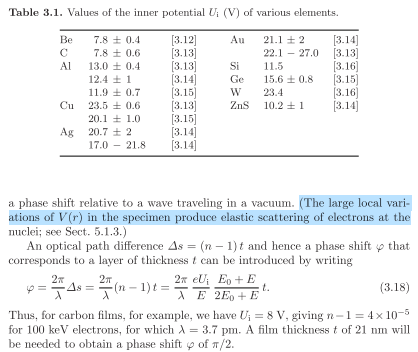

Where E is the electron energy, E_o the electron rest energy

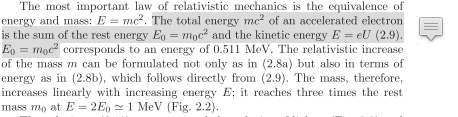

From hyperphysics

A dedicated paper claims:

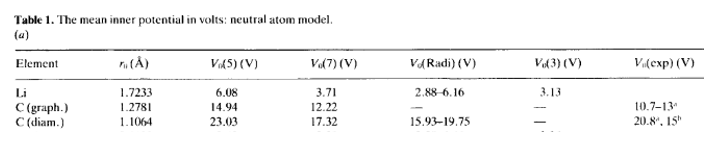

#### Verification

Wavelength verfified with hyperphysics comparison at 3 and 10 keV

Phase verified with Reimer example:

## Simple analysis

addpath('C:\Users\johns\Documents\Github\QEM-MATLAB');
load ImpVariables.mat;
KE = 1*c.kilo;
thickness = [0.355] * c.nano; % film thickness in nm
innerPot = [13.24]; %eV

pc = sqrt(KE^2 + 2*KE*c.eRestMass_eV) %output in eV still

pc = 3.1984e+04

lambda = c.hc_eVnm/pc*c.nano %wavelength in m

lambda = 3.8764e-11


deltaPhase = 2*pi/lambda * (innerPot/KE) *...
    ((c.eRestMass_eV+KE)/(2*c.eRestMass_eV+KE)) * thickness

deltaPhase = 0.3813

deltaPhasePiOver2 = deltaPhase*2/pi

deltaPhasePiOver2 = 0.2427

## Diffraction

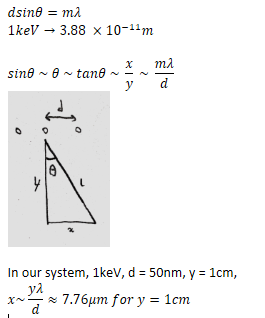

d =  0.246*c.nano;
y = 10*c.milli;

deltaX = y*lambda/d

deltaX = 0.0016

disp(sprintf('Delta X is ', deltaX/c.milli, 'mm'))

Delta X is 


theta = asin(lambda/d)*180/(pi);